% Convex Optimization
% Hw5
% Q3_b


clear;
clc;
close all;

% Load Given Data
run('nonlin_meas_data.m')

% 
row=zeros(1,m);

row(1)=-1;
row(2)=1;

col=zeros(1,m-1);
col(1)=-1;

B=toeplitz(col,row); % to get (zi+1 - zi) and (yi+1-yi)

cvx_begin
    variable x(n);
    variable z(m);
    minimize(norm(z-A*x,2)); % Likelihood Function of Part (a) sum((zi-aiT*x)2) over i
    subject to
    (1/beta)*B*y<=B*z;    % Constraints in Part (a)
    B*z<=(1/alpha)*B*y;
cvx_end

 
Calling SDPT3 4.0: 899 variables, 305 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 305
 dim. of socp   var  = 301,   num. of socp blk  =  1
 dim. of linear var  = 598
 20 linear variables from unrestricted variable.

 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.2e+00|6.4e+00|6.3e+02| 5.150400e+01| 0:0:00|6.3e+02|1.0e+00|1.0e+00| chol 1   1
 1|0.429|0.429|1.0e+00|5.6e+00|7.5e+02| 6.157013

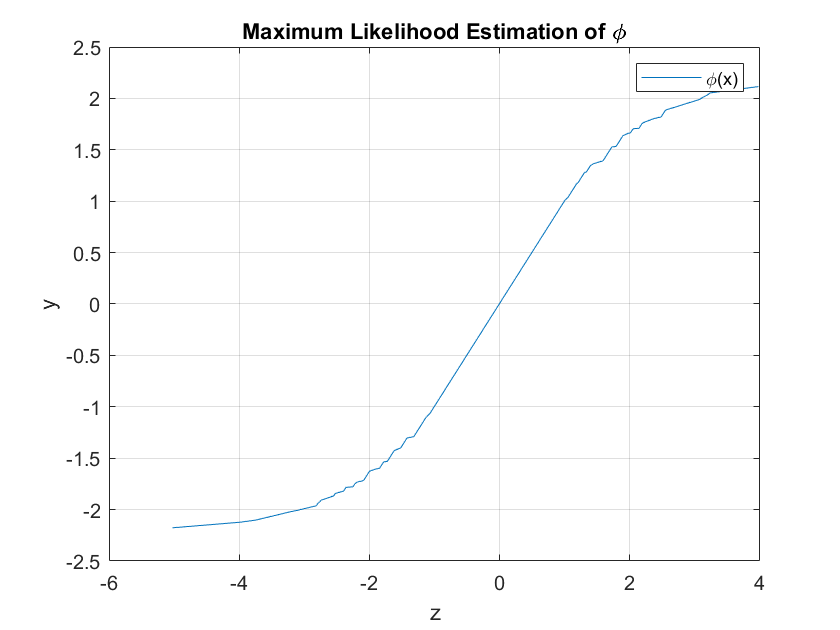

plot(z,y)
ylabel('y')
xlabel('z')
title('Maximum Likelihood Estimation of \phi')
grid on
legend('\phi(x)')

disp('Estimated values of x: ')

Estimated values of x: 


disp(x')

    0.4819   -0.4657    0.9364    0.9297



disp('Estimated Values of PHI: ')

Estimated Values of PHI: 


disp(z')

  Columns 1 through 12

   -5.0246   -3.9897   -3.7440   -3.2487   -3.0648   -3.0638   -3.0628   -2.8156   -2.7956   -2.7542   -2.7432   -2.6744

  Columns 13 through 24

   -2.5478   -2.5258   -2.3951   -2.3821   -2.3601   -2.2530   -2.2410   -2.2220   -2.1807   -2.1797   -2.1128   -2.0874

  Columns 25 through 36

   -2.0194   -2.0084   -1.9994   -1.8991   -1.8437   -1.8437   -1.8347   -1.8257   -1.8087   -1.7817   -1.7245   -1.6995

  Columns 37 through 48

   -1.6935   -1.6905   -1.6555   -1.6525   -1.6205   -1.5185   -1.5035   -1.4895   -1.4845   -1.4415   -1.4335   -1.4225

  Columns 49 through 60

   -1.3189   -1.2859   -1.2839   -1.2809   -1.2359   -1.2189   -1.2029   -1.1899   -1.1839   -1.1799   -1.1679   -1.1489

  Columns 61 through 72

   -1.1489   -1.1399   -1.1339   -1.0716   -1.0686   -1.0666   -1.0596   -1.0326   -1.0136   -0.9886   -0.9766   -0.9656

  Columns 73 through 84

   -0.9626   -0.9486   -0.9446   -0.9286   -0.9276   -0.9186   -0.9146   -0.9146   -0.9126   -